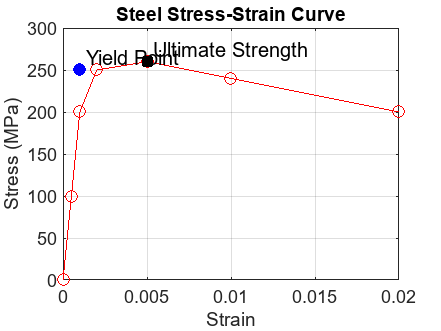

% Steel Stress-Strain Curve Plotter

strain = [0 0.0005 0.001 0.002 0.005 0.01 0.02];
stress = [0 100 200 250 260 240 200]; 

figure;
plot(strain, stress, 'r-o');
xlabel('Strain');
ylabel('Stress (MPa)');
title('Steel Stress-Strain Curve');
grid on;

[ultimate_stress, idx] = max(stress);
hold on;
plot(strain(idx), ultimate_stress, 'ks', 'MarkerFaceColor','k');
text(strain(idx), ultimate_stress, ' Ultimate Strength', 'VerticalAlignment','bottom');

yield_stress = 250; % Approximate
plot(0.001, yield_stress, 'bo', 'MarkerFaceColor','b');
text(0.001, yield_stress, ' Yield Point', 'VerticalAlignment','bottom');